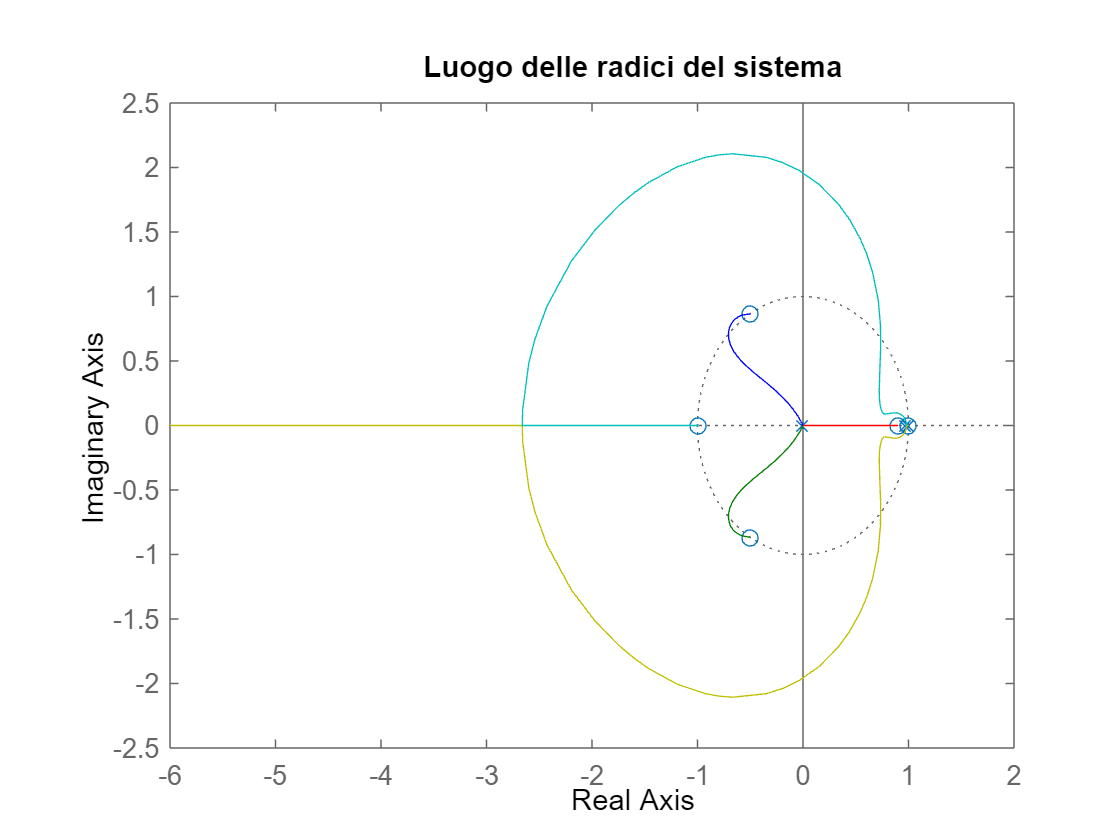

kcrit = 9.5134

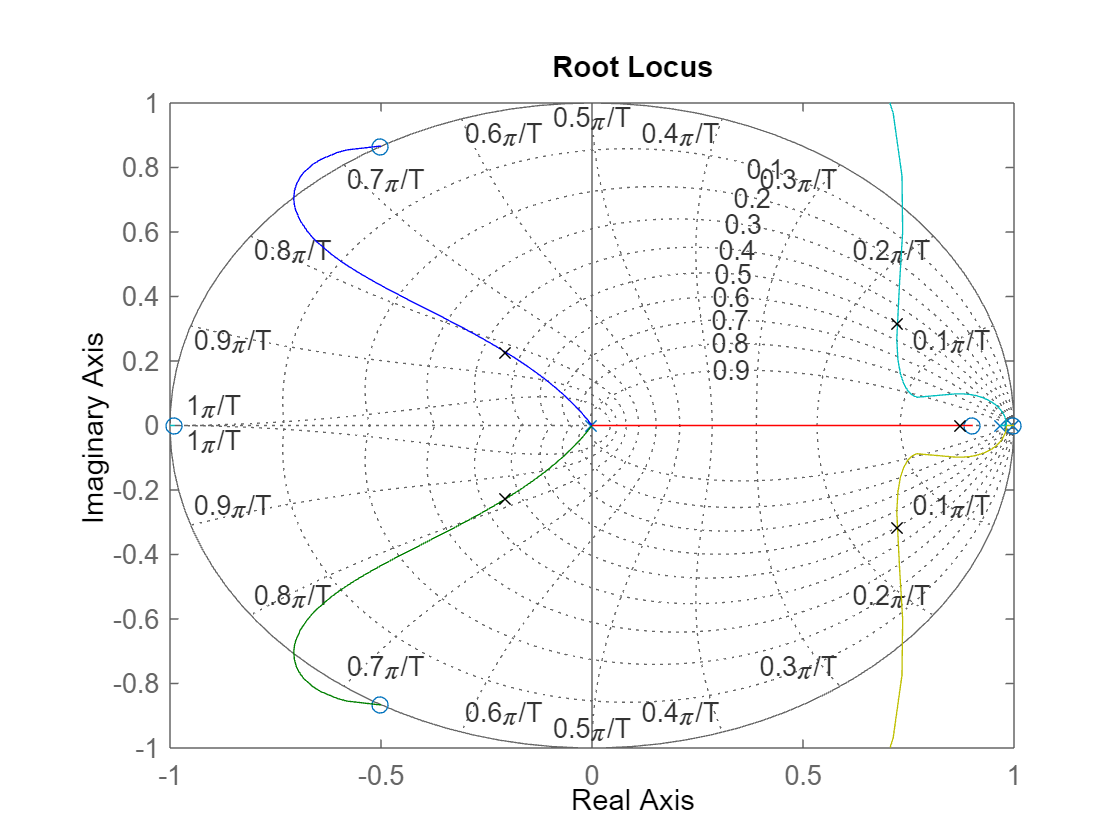

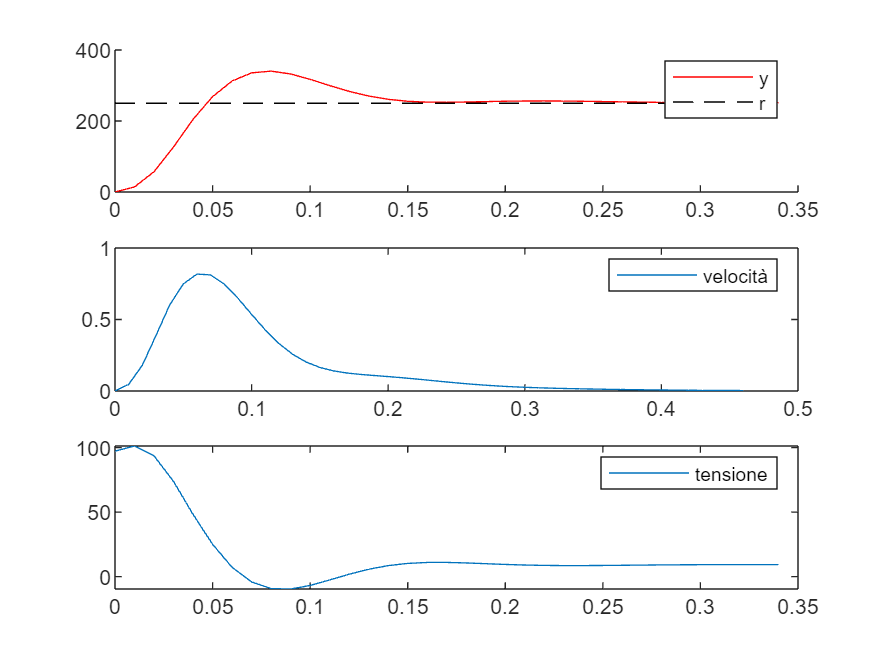

close all

clear
clc

Ts = 0.01;

mot.k = 2.8;
mot.T = 0.3;
P = c2d(tf([mot.k], [mot.T 1 0]), Ts, "zoh");

Ti = 0.092;
z = tf('z', Ts);
s = (1 - z^-1) / Ts;
C = minreal(1 + 1 / (Ti * s), 1e-6);

H = (1 - z^-3) / (3 * Ts);

L = C * P * H;
close all
figure(1)
rlocus(L)
title("Luogo delle radici del sistema")
kcrit = margin(L)

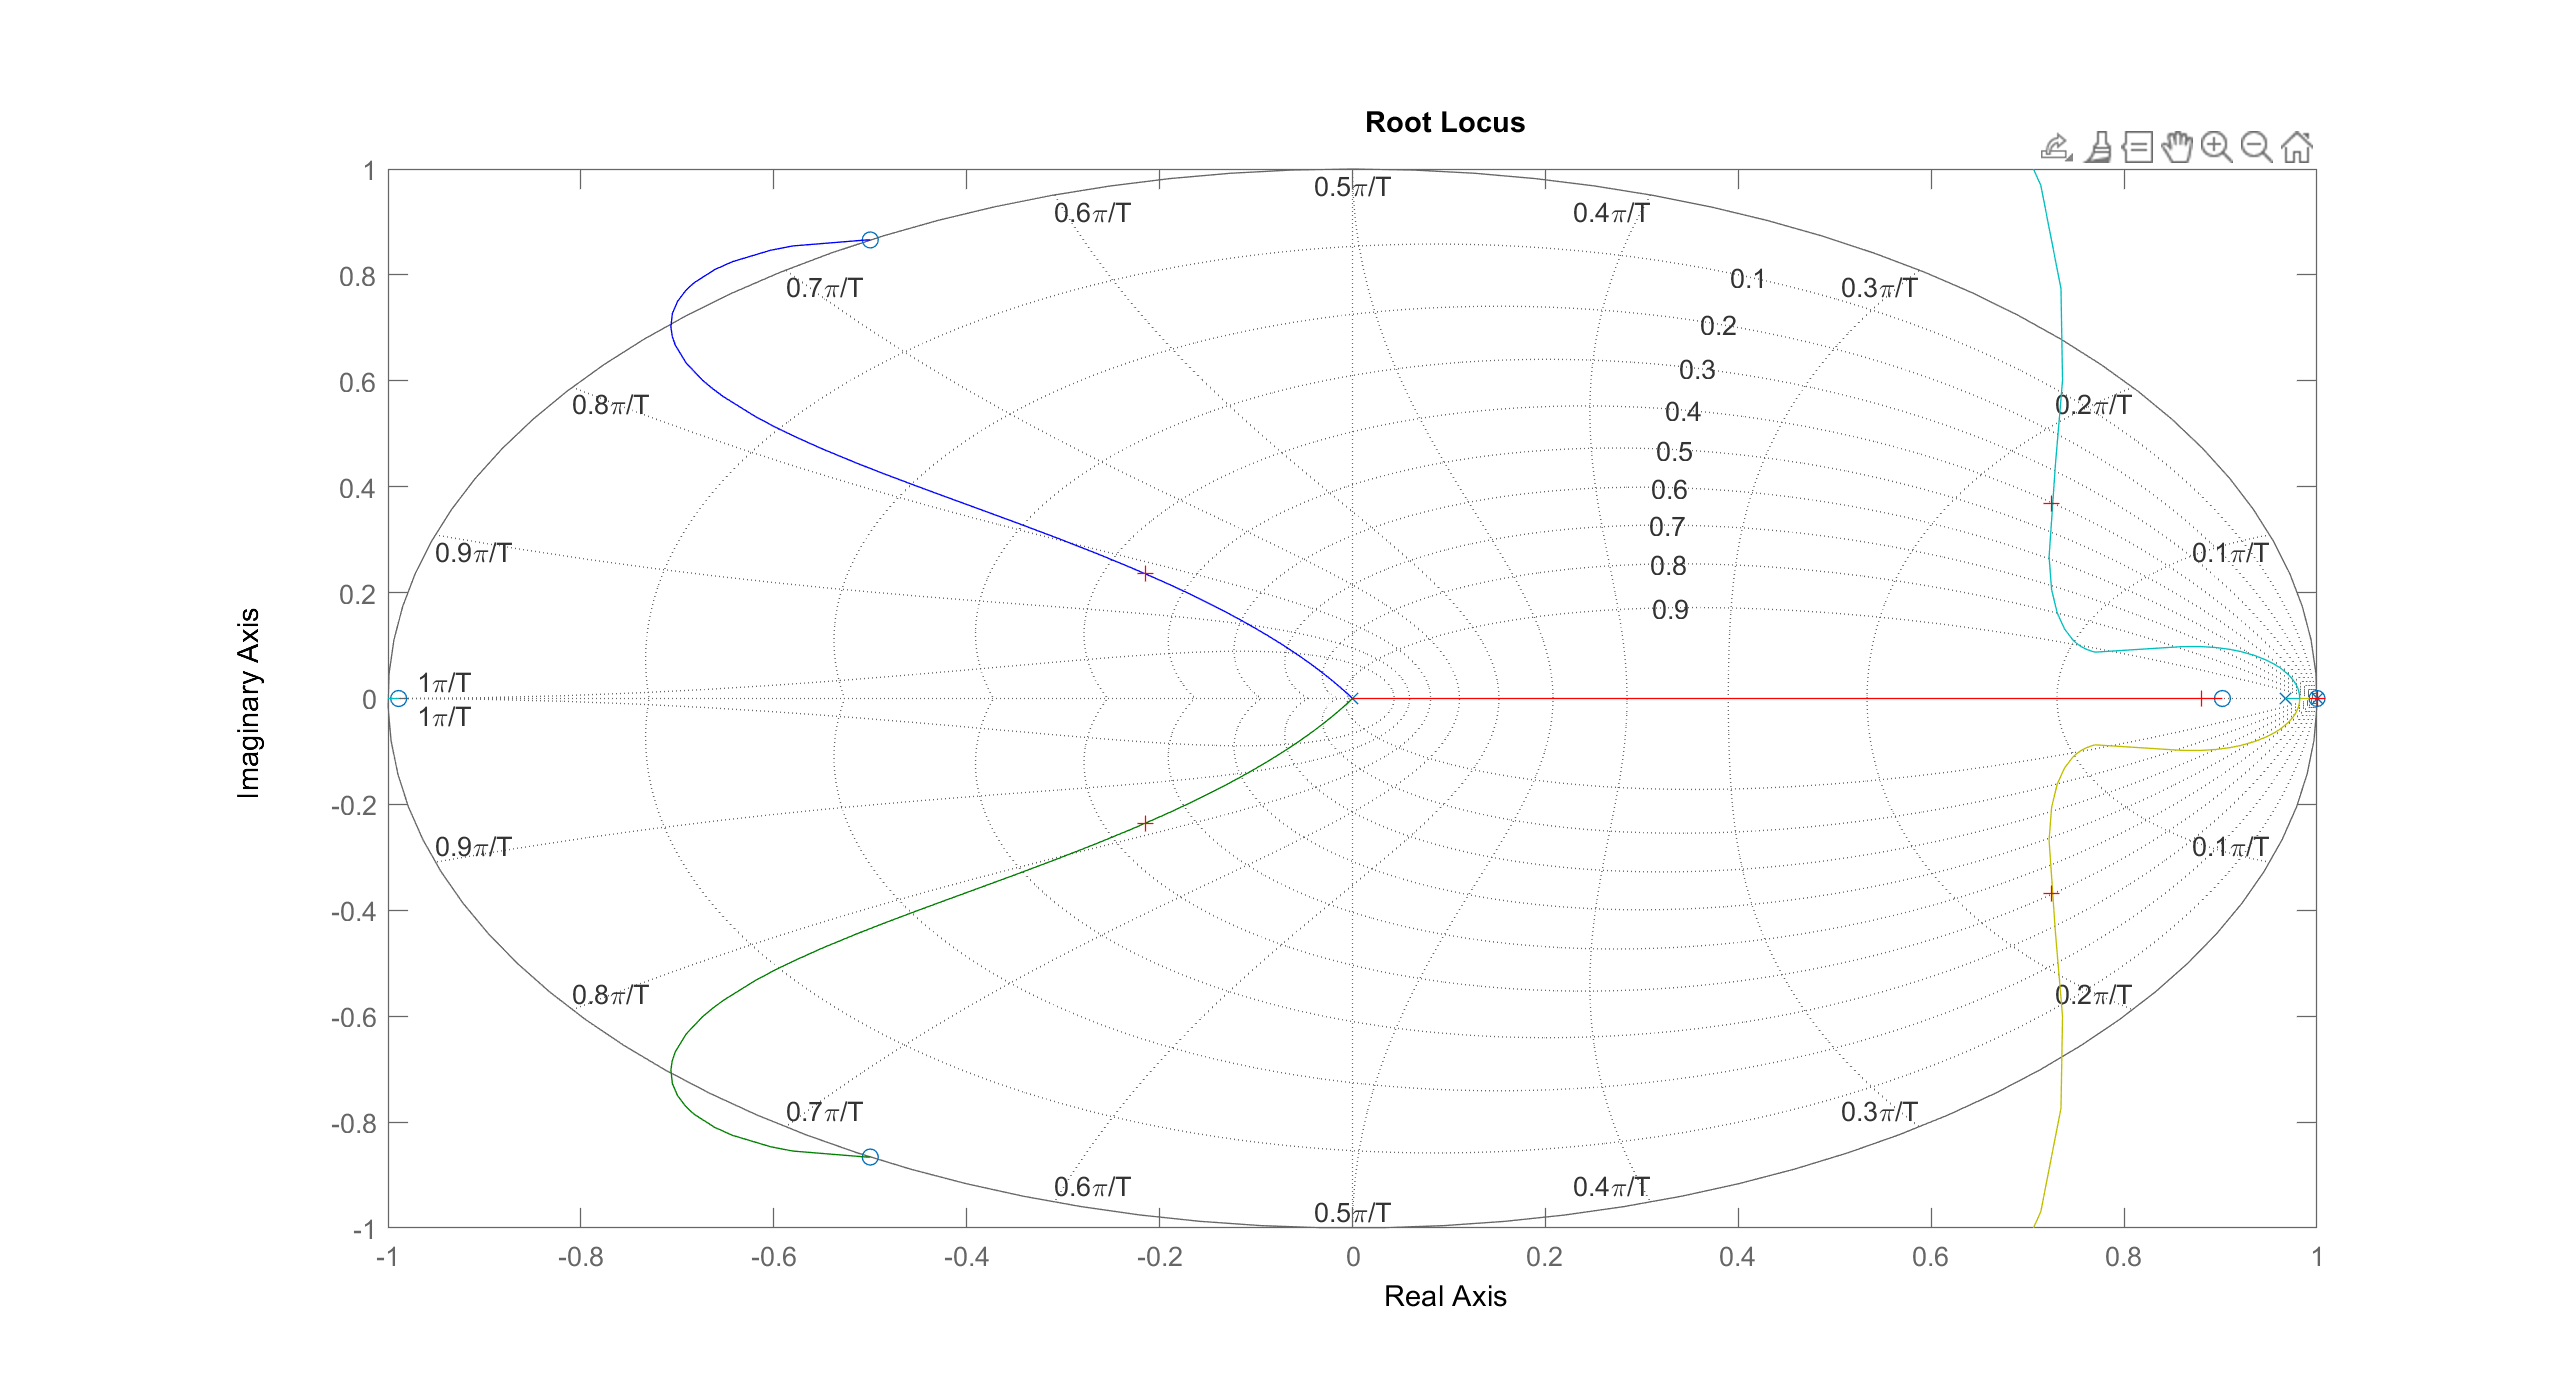

Select a point in the graphics window


selected_point = 0.7258 + 0.3683i

K = 3.8783

close all
figure(2)
hold on
zgrid on
rlocus(L)
xlim([-1 1])
ylim([-1 1])
K = rlocfind(L)

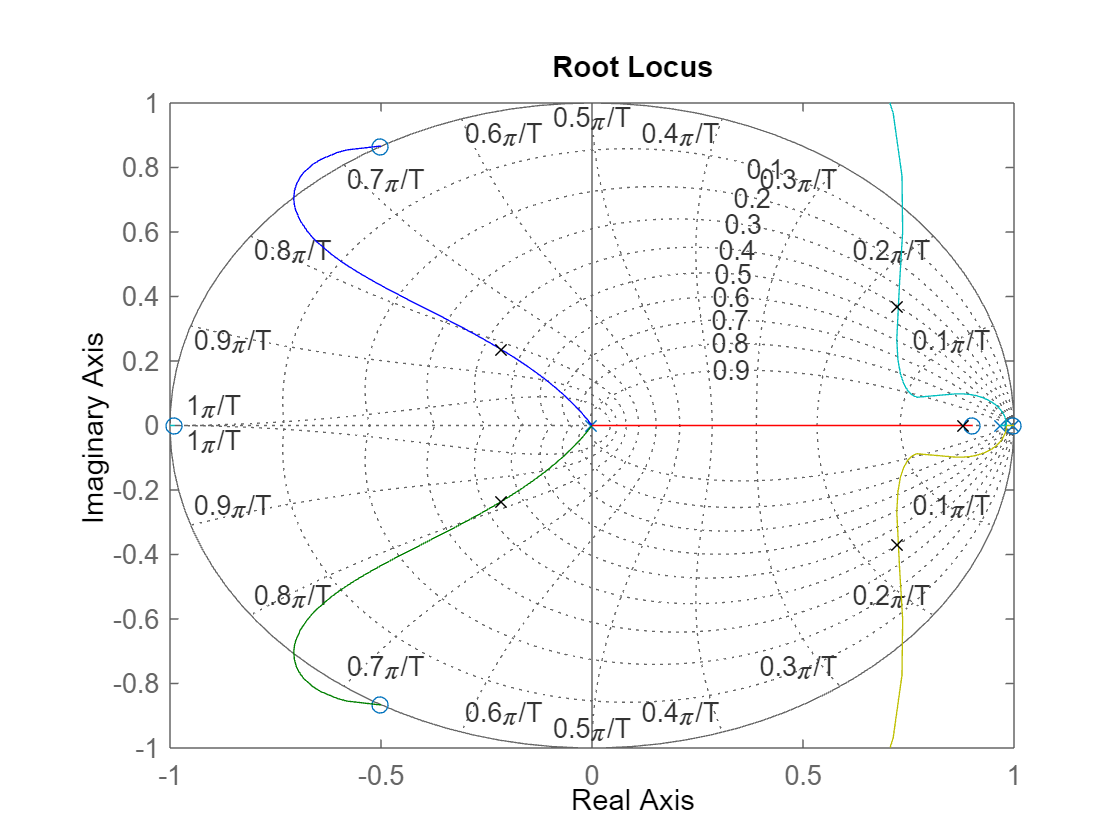

T = minreal(feedback(K * L, 1), 1e-6);
poles = pole(T);
figure(3)
hold on
zgrid on
rlocus(L)
plot(real(poles), imag(poles), "kx")
xlim([-1 1])
ylim([-1 1])

T = minreal(feedback(K * L, 1), 1e-6);
G = minreal(P * H / (1 + P * H * K * C), 1e-6);
W = minreal(K * C / (1 + P * H * K * C), 1e-6);

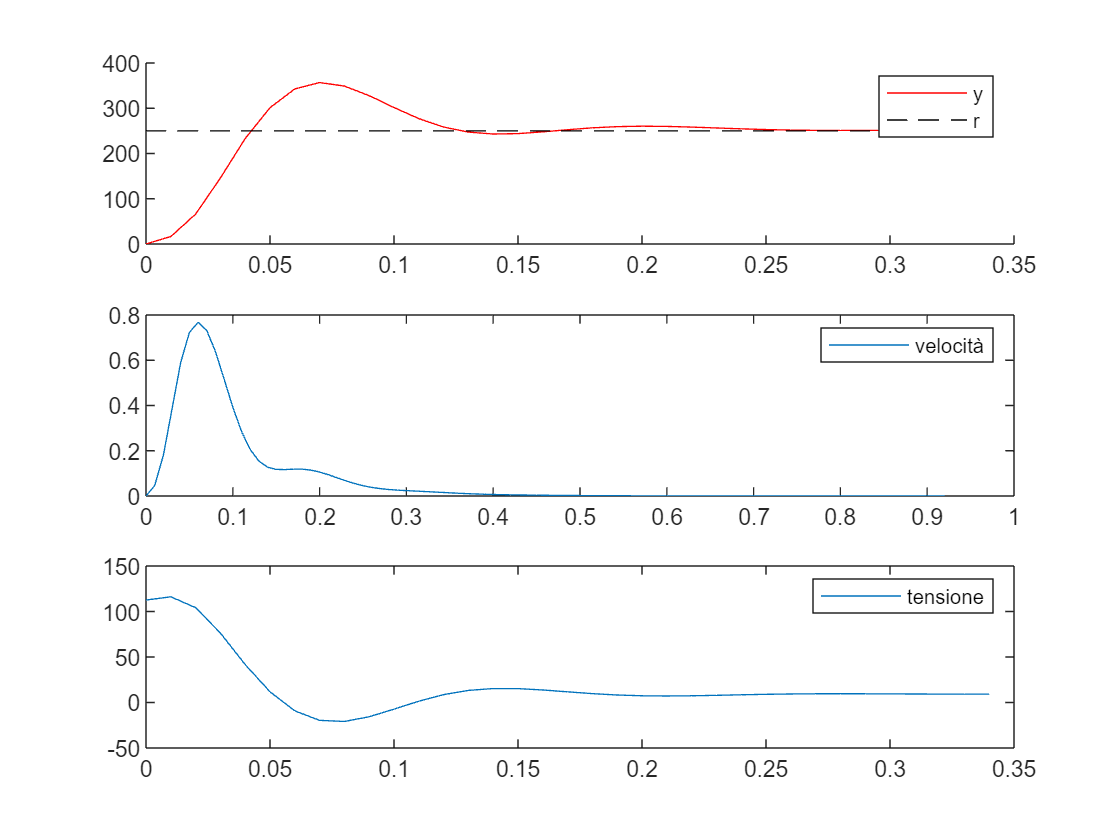

rpm2rads = 2 * pi / 60;
rads2rpm = 60 / (2 * pi);
opt1 = stepDataOptions("StepAmplitude", 250 * rpm2rads);
opt2 = stepDataOptions("StepAmplitude", 3);
[yt, tt] = step(T, opt1);
[yg, tg] = step(G, opt2);
[yw, tw] = step(W, opt1);
close all
figure(3)
subplot(3, 1, 1)
hold on
plot(tt, yt * rads2rpm, "r")
plot([tt(1), tt(end)], [250, 250], "k--")
legend("y", "r")

subplot(3, 1, 2)
plot(tg, yg)
legend("velocità")

subplot(3, 1, 3)
plot(tw, yw)
legend("tensione")

16.32